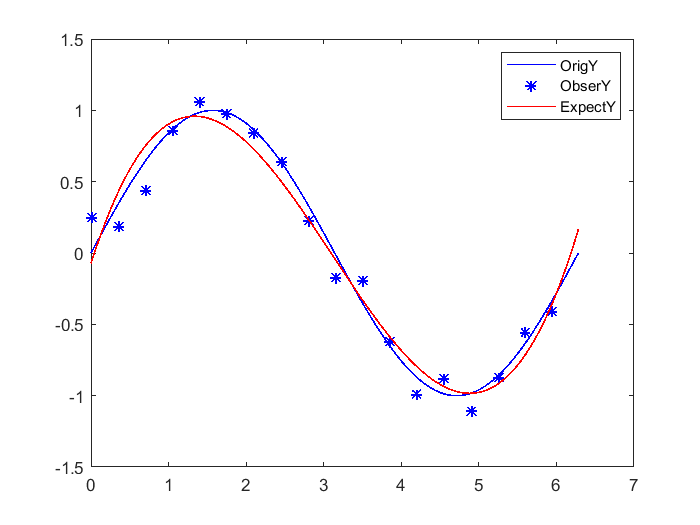

% 线性最小二乘法拟合主要是polyfit函数，而polyfit函数的核心是qr函数，即 QR decomposition algorithm ！ 
% 最核心的算法其实是：QR分解 
% So, where to find source code of qr() of MATLAB ！！！   [leastsq() of Python ]
clear all;
clc ;
close all;

OriginalX = 0:0.001:2*pi;
OriginalY = sin(OriginalX);

RealX = 0:0.35:2*pi;
RealY = sin(RealX);
ObseNoise_VAR = 0.01; % 观测噪声的方差 ObserveNoise_VAR   
% 观测噪声: sqrt(ObseNoise_VAR)*randn(1,length(RealX))  工程上采用 高频n次采样均值 降低检测误差
ObserY = RealY + sqrt(ObseNoise_VAR)*randn(1,length(RealX));% + 0.1; % 偏移 用于核对拟合效果

coef = myfunc(RealX,ObserY);  % 三次基本足够 
ExpectY = polyval(coef,OriginalX); % 在硬件C上最好不要超过四次 并且变量都需强转为single以提高速度并节省内存
    plot(OriginalX,OriginalY,'b',RealX,ObserY,'b*',OriginalX,ExpectY,'r','LineWidth',1)
    legend('OrigY', 'ObserY', 'ExpectY');